clc; clearvars;

theta = linspace(0,pi/2,1e3);

tantheta = tan(theta);

d = 100 .* (tantheta - theta)./tantheta;

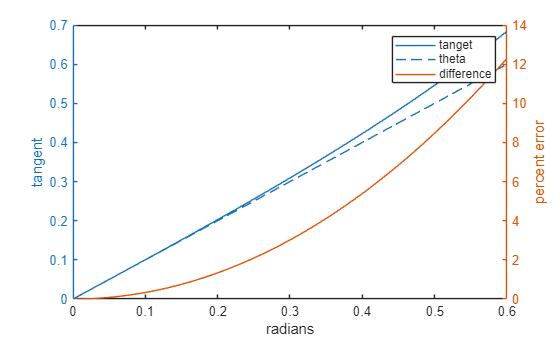

figure

yyaxis left
hold on
plot(theta, tantheta,'DisplayName',"tanget")
plot(theta, theta, 'DisplayName',"theta")
hold off
xlabel("radians")
ylabel("tangent")
xlim([0, .6])
% ylim([0 5])
legend

yyaxis right
plot(theta,d,"DisplayName","difference")
ylabel("percent error")